Jordan Carlson - V00714886

Question 1.

Import the data and give it a variable name

originalData = importdata('Assignment6.mat')

originalData =     7.3259   -0.4663    9.8626    3.3426   19.2877   -1.1585   -7.7808   25.5149   15.7297   21.4196    6.5270   28.5044    0.0163    8.8675   -7.5179   -2.5703   -3.7289   -4.9954  -13.4687   20.1894    0.3003    7.1002   14.8095   -5.7124    0.6369
    1.6181    1.0071   -5.9292   -3.2623   -6.9211   11.5321   17.4389   -9.8437   19.9557    2.8332    2.3035  -14.8832    2.6894    2.0294    0.2777   -8.6787    2.8834    8.2864   19.8758    4.0268   -0.1837  -20.0186  -23.1974    8.0427   -2.4141
   14.8947    0.5897    9.5317   -1.6832   32.1463    4.2200    6.5778    0.6085   15.2116   17.7187   11.4492   18.4827   -6.0583   -6.7288   20.1887   -4.1687    5.0159   13.2940  -13.3144   -7.5147   -5.6693    6.2090    9.7077    6.9402   14.4357
    6.3207   10.5019   17.0988   29.1190    4.7897  -11.1457   -2.1916   -6.4610   -0.9441   18.1130    0.6732   24.8650   25.6203   16.5206   12.6189   10.1078  -10.3068  -15.2698   -5.5847  -30.2633   -5.9135  -15.0295  -14.6404  

MatLabs built-in PCA, 2 output function will result in a 25x25 Principal Component Coefficient Matrix and a 10000x25 Principal Component Score Matrix.

[coeff,score]=pca(originalData)

coeff =    -0.0649   -0.1264    0.2347    0.1469   -0.3009   -0.2041   -0.2252    0.4225   -0.1679   -0.2493   -0.3942    0.1637    0.3289   -0.0370    0.0598   -0.0836   -0.3184   -0.1587   -0.0724    0.0949   -0.0863   -0.0171    0.0113   -0.0153    0.0122
   -0.0428   -0.1960    0.0069    0.0812    0.1237    0.0756    0.1541    0.1471   -0.1222    0.6842   -0.4385   -0.3967    0.1251    0.0928    0.0001   -0.0798    0.0728    0.0186   -0.0939   -0.0140   -0.0511    0.0121   -0.0415    0.0610   -0.0214
   -0.2368    0.3137    0.0039    0.0278    0.0813    0.3067    0.2462    0.2124   -0.1700   -0.5091   -0.2129   -0.3859   -0.1450    0.2576    0.0863    0.0458    0.1912   -0.0841   -0.0908   -0.0462    0.0153    0.0235   -0.0477    0.0453    0.0051
    0.1610   -0.0372   -0.0031   -0.4262    0.0661    0.0784    0.1731   -0.0824   -0.0270   -0.0245   -0.0630   -0.0182    0.1781   -0.1478   -0.0226    0.1072   -0.0377   -0.3488   -0.2117   -0.0708   -0.0101   -0.3906   -0.1376   -0.304

score =   -27.5648   -5.0280  -19.9307   27.1052   14.0980   -8.3561  -36.1154  -63.8088   26.3291  -11.5396   19.9557   -6.2548    0.2460    5.4977   14.3974  -20.4909    8.8157  -24.7901    0.9231   -8.1361  -24.8859   14.8997  -22.0527   -2.5943   -8.6308
   -9.9112   14.0975  -19.1533    9.2307    8.7589    4.8116  -74.5761  -75.1149   46.3071    4.8736    2.7638   -7.6689   -0.7839   22.3607   -4.5593   18.1962   -5.9461    1.8066   -9.6711   33.7212   -7.7362    0.7055  -19.1119    5.6387  -21.8171
  -29.1472   -8.1708   -3.9728   22.7969    0.8086    4.7071  -24.8081  -58.2705   44.8369   -7.6448    6.4553    3.0354  -14.9009   10.3405   23.7089    0.0654   -9.4806   -6.1740   -4.6026   21.1676  -29.3258   23.9256  -21.4420   -5.3027   -3.5565
  -44.5819   -6.8477  -12.6838  -10.7783   -4.4193    1.1343  -52.1882  -71.2086   47.4760   -5.2432  -15.8376  -12.5016  -23.1055   11.7979   -4.9698   -4.7426   19.2834  -15.7228  -34.7077    1.2592  -27.2695   -2.1650   -3.1946  -26.547

To reduce the dimensionality from the PCA values, concatenating the Principal Component Coefficient Matrix to the intended dimension can be achieved with the code coeff=coeff(:,1:k), where k is the final dimension. This final dimension contains the most accurate data that represents the original matrix

newCoeff=coeff(1:2,:)

newCoeff =    -0.0649   -0.1264    0.2347    0.1469   -0.3009   -0.2041   -0.2252    0.4225   -0.1679   -0.2493   -0.3942    0.1637    0.3289   -0.0370    0.0598   -0.0836   -0.3184   -0.1587   -0.0724    0.0949   -0.0863   -0.0171    0.0113   -0.0153    0.0122
   -0.0428   -0.1960    0.0069    0.0812    0.1237    0.0756    0.1541    0.1471   -0.1222    0.6842   -0.4385   -0.3967    0.1251    0.0928    0.0001   -0.0798    0.0728    0.0186   -0.0939   -0.0140   -0.0511    0.0121   -0.0415    0.0610   -0.0214


The data matrix with the altered dimension can be reconstructed with the formula newMatrix = (score)*(newCoeff)' and this gives us our final matrix for submission.

Q1answer = (score)*(newCoeff)'

Q1answer =   -25.7526  -22.2095
  -31.4604  -20.7361
  -18.1838  -21.1535
  -26.7578  -11.2413
  -37.0037  -16.1247
  -46.2125  -15.0691
   -4.9017  -20.9725
  -40.7383  -24.5902
  -39.8000  -19.7241
  -31.5042  -17.0175


Question 2.

Using the  25x25 Principal Component Coefficient Matrix and a 10000x25 Principal Component Score Matrix from question 1, we can now concatenate the coefficient matrix to 5 dimensions to begin using the expecation maximization algorithm

newCoeffQ2=coeff(1:5,:)

newCoeffQ2 =    -0.0649   -0.1264    0.2347    0.1469   -0.3009   -0.2041   -0.2252    0.4225   -0.1679   -0.2493   -0.3942    0.1637    0.3289   -0.0370    0.0598   -0.0836   -0.3184   -0.1587   -0.0724    0.0949   -0.0863   -0.0171    0.0113   -0.0153    0.0122
   -0.0428   -0.1960    0.0069    0.0812    0.1237    0.0756    0.1541    0.1471   -0.1222    0.6842   -0.4385   -0.3967    0.1251    0.0928    0.0001   -0.0798    0.0728    0.0186   -0.0939   -0.0140   -0.0511    0.0121   -0.0415    0.0610   -0.0214
   -0.2368    0.3137    0.0039    0.0278    0.0813    0.3067    0.2462    0.2124   -0.1700   -0.5091   -0.2129   -0.3859   -0.1450    0.2576    0.0863    0.0458    0.1912   -0.0841   -0.0908   -0.0462    0.0153    0.0235   -0.0477    0.0453    0.0051
    0.1610   -0.0372   -0.0031   -0.4262    0.0661    0.0784    0.1731   -0.0824   -0.0270   -0.0245   -0.0630   -0.0182    0.1781   -0.1478   -0.0226    0.1072   -0.0377   -0.3488   -0.2117   -0.0708   -0.0101   -0.3906   -0.1376   -

newMatrixQ2 = (score)*(newCoeffQ2)'

newMatrixQ2 =   -25.7526  -22.2095  -12.0600  -18.5553   -3.6019
  -31.4604  -20.7361  -27.8518  -25.1602  -29.8108
  -18.1838  -21.1535  -12.3908  -23.5811    9.2567
  -26.7578  -11.2413   -4.8238    7.2210  -18.0999
  -37.0037  -16.1247  -20.9907   -7.2597    3.2830
  -46.2125  -15.0691   -9.8228  -12.2476    0.2362
   -4.9017  -20.9725  -10.7842    3.1996  -23.6131
  -40.7383  -24.5902  -39.1290  -15.4010  -12.5619
  -39.8000  -19.7241  -23.4978  -30.7802  -28.1970
  -31.5042  -17.0175  -18.4926  -37.3530  -19.3542


To begin the expectation-maximization algorithm, we can derive an estimator from our data to use as our estimator in the first iteration of the algorithm.

initialSigma = (cov(newMatrixQ2))^.5

initialSigma =    18.7346    0.3700   -0.7980   -1.9324    0.8325
    0.3700   16.5934   -0.8376   -0.2533    2.2780
   -0.7980   -0.8376   20.0360   -1.4711   -0.7087
   -1.9324   -0.2533   -1.4711   17.4792   -2.4358
    0.8325    2.2780   -0.7087   -2.4358   15.9232


initialMean = mean(newMatrixQ2)

initialMean = 	1.0e+-12 *

    0.0659    0.1032    0.0449   -0.0132   -0.0124


normalization = 1/((2*(pi))^.5)^2.5

normalization = 0.1005

For the expectation step of the algorithm: Using these estimators, we can generate a new sample for the maximization step.

expectationMatrix = mvnrnd(initialMean,initialSigma, 10000)/normalization

expectationMatrix =    29.1006  -59.0712   49.9500  -24.1228   -7.5672
  -56.0130  -26.6868  -25.4454   -2.8987   40.6695
   24.2382   28.8449  -31.0575  -48.3313   36.9003
   10.4520  -36.3008   28.9545    8.2194   27.0221
    6.0204   59.6539   12.1567  -56.0199   28.3371
  -14.2257   34.4992  -81.3493    6.0676   39.9507
   40.2588  -14.2888  -45.4988   60.7937  -71.8484
    7.4925  -20.7131   15.6170  -23.4120   72.6068
  -17.1617  -12.8299   62.6404   -8.9655   38.5054
  -28.9721   44.7805   36.8343  -32.0250    4.4076


For the maximixation step of the algorithm: from the new expectation values we can derive a new, more accurate mean vector and covariance.

nextSigma = (cov(expectationMatrix))^.5

nextSigma =    42.6772    0.4339   -0.9974   -2.0392    0.8851
    0.4339   39.6984   -0.9683   -0.3267    2.6894
   -0.9974   -0.9683   44.8694   -1.8833   -0.8485
   -2.0392   -0.3267   -1.8833   41.5147   -3.0718
    0.8851    2.6894   -0.8485   -3.0718   39.3878


nextMean = mean(expectationMatrix)

nextMean =    -0.0621   -0.4887    0.0427   -0.1641   -0.0546


Iterating the last two steps, the expectation-maximization mean vector and covariance should converge

for a = 1:2

expectationMatrix = mvnrnd(nextMean,nextSigma, 10000)
nextSigma = (cov(expectationMatrix))^.5
nextMean = mean(expectationMatrix)

end

expectationMatrix =    -4.2602   -0.6109    4.6766    1.4826   -7.8452
   -0.4129   15.7506    7.5562    3.5570    6.6630
   -3.5536   -4.9508  -11.6370   12.5417   -6.8795
   -0.5764   11.7170    0.3510   -6.2618    8.0398
   -1.3302  -14.4436   -1.3448    3.6643    5.9246
   11.8490   14.7353    1.0760   -3.9644   13.4736
   -5.2853   -5.5922    3.8540   -6.5352   -7.0825
   -9.6364    1.7603    3.8332   -0.3687   -2.3771
   -2.9794   -0.6112    5.7565    3.6585   -0.0095
    3.3296    5.9008    1.4522   -3.3789   -5.0310


nextSigma =     6.5551    0.0600   -0.0166   -0.1656    0.0700
    0.0600    6.3319   -0.1030   -0.0214    0.2103
   -0.0166   -0.1030    6.5915   -0.1367   -0.0866
   -0.1656   -0.0214   -0.1367    6.3895   -0.2096
    0.0700    0.2103   -0.0866   -0.2096    6.3173


nextMean =    -0.0085   -0.4368    0.1180   -0.3117   -0.0553


expectationMatrix =    -1.4111   -2.7186   -3.8253   -2.5229   -3.0096
   -2.4980    0.3013    7.2713   -0.2505   -2.2814
   -0.1396   -0.8004   -1.6418    2.0813   -2.8605
   -2.9537   -1.6993    3.4352    1.6764   -2.7274
   -3.2604   -0.7547   -0.4652   -1.9501    1.2905
    2.9902   -0.9215    0.5023   -0.1883    1.9856
    1.3966    1.8339   -0.2821    0.0109    0.0542
   -2.6963    2.6226    3.2562    1.5692    1.7568
    4.2287   -1.2603   -3.4203   -0.4790   -0.4885
   -0.6196    2.1768   -1.3515    0.7650   -1.2595


nextSigma =     2.5572   -0.0043    0.0134   -0.0401   -0.0015
   -0.0043    2.5192   -0.0066    0.0046    0.0329
    0.0134   -0.0066    2.5783   -0.0229   -0.0261
   -0.0401    0.0046   -0.0229    2.5044   -0.0387
   -0.0015    0.0329   -0.0261   -0.0387    2.5343


nextMean =    -0.0124   -0.4069    0.1241   -0.2967   -0.0008


The values have indeed converged, and we are left with the covariance and mean vector for our estimated probability function. As described in the question, the mean and covariance is the sum of our 5 most accurate distributions that represent the data's probability distribution.

This is a spherical gaussian with mean vector of the final value of (nextMean), and the covariance of the final value of (nextSigma)^2

Question 3.

Using the variance and means from the reduced, 5 dimension matrix from the beginning of Q2, parzen window estimate can be created for each data point.

Count and parzenSum are initialized to keep track of the parzen windows, and final sum of parzen window distributions.

count = 0

count = 0

parzenSum = 0

parzenSum = 0

Aparzen window will be created for each data point

for j = 1:1

There is a parzen window for each row, which represents a sample in 5d space.

currentWindow = newMatrixQ2(j,:)

The parzen window uses a bandwidth of 1/sqrt(n), evaluated from the mean calculated for the initial matrix which was created in Q2.

exponential = -((initialMean-currentWindow)*(initialMean-currentWindow)')/2*.01^2
currentParzen = 1/(((2*(pi))^2.5))*exp(exponential)


The parzen sum is added for the final distribution creation, and the count is incremented for debugging

parzenSum = parzenSum + currentParzen
count = count + 1

end

currentWindow =   -25.7526  -22.2095  -12.0600  -18.5553   -3.6019


exponential = -0.0830

currentParzen = 0.0093

parzenSum = 0.0093

count = 1

The final parzen estimate can then be derived by dividing by n


parzenEstimate = parzenSum/(10000)

parzenEstimate = 9.3008e-07

The final parzen window estimate has accumulated to .0093.

Question 4.

The estimated distribution in Question 1 derived from PCA was more simple to calculate, but the estimated distribution using the expectation-maximization algorithm was likely the more accurate distribution for the data points. 

Using the expecation-maximization algorithm, the data points can be re-tested against the estimated distribution to check the distribution many times before the final estimated parameters are decided, and the more times it is iterated, the greater the likelihood that the parameters are accurate.

The PCA method may, however, be more beneficial in finding trends in the data than the expectation-maximization method.

Question 5.

In order to plot these 5D diagrams, similarly to Q1s process we need to translate the 5D distributions to 2D and 3D.

The 2D variance and 3D covariances can be derived from dimension reduction from PCA as used in Q1

[Q2SigmaCoeff,Q2SigmaScore]=pca(nextSigma)

Q2SigmaCoeff =     0.3070   -0.5967    0.5923    0.0465
   -0.3577    0.0713   -0.1351    0.8098
    0.7264    0.2304   -0.4734   -0.0179
   -0.2063    0.6590    0.4491   -0.3259
   -0.4556   -0.3891   -0.4529   -0.4854


Q2SigmaScore =     0.7911   -1.5236    1.5117    0.1019
   -0.9373    0.1964   -0.3326    1.9954
    1.8819    0.6061   -1.1900   -0.0577
   -0.5438    1.7099    1.1489   -0.8221
   -1.1919   -0.9889   -1.1381   -1.2175


ThreeDCoeffQ2Sigma=Q2SigmaCoeff(1:2,:)

ThreeDCoeffQ2Sigma =     0.3070   -0.5967    0.5923    0.0465
   -0.3577    0.0713   -0.1351    0.8098


ThreeDQ2Sigma = (Q2SigmaScore)*(ThreeDCoeffQ2Sigma)'

ThreeDQ2Sigma =     2.0522   -0.5135
   -0.5093    2.0100
   -0.4915   -0.5158
   -0.5450   -0.5045
   -0.5065   -0.4763


In order to achieve a symmetric, positive matrix for use in the distribution, the covariance matrix can be concatenated and taken the absolute value of. The mean matrix can also be concatenated.

ThreeDQ2Sigma = (ThreeDQ2Sigma(1:2,1:2))

ThreeDQ2Sigma =     2.0522   -0.5135
   -0.5093    2.0100


ThreeDQ2Sigma = (cov(abs(ThreeDQ2Sigma)))

ThreeDQ2Sigma =     1.1904   -1.1546
   -1.1546    1.1198



ThreeDQ2Mean = nextMean(:,1:2)

ThreeDQ2Mean =    -0.0124   -0.4069


The 'rng' function allows randomly generated numbers to be repeated for repeatability in the creation of distributions, and 100 numbers are randomly generated for plotting distributions.

rng=('default')

rng = 'default'

RandomVariables = rand(100, 1)

RandomVariables =     0.3311
    0.0717
    0.9647
    0.2714
    0.5285
    0.0847
    0.3765
    0.2771
    0.2888
    0.3022


Question 2's 3D plot from the estimated p(x)

Q2Distribution = mvnrnd(ThreeDQ2Mean,ThreeDQ2Sigma,100)

Q2Distribution =     0.9220   -1.3132
   -0.3749   -0.0554
    2.1710   -2.5246
    1.5388   -1.9114
   -0.5271    0.0923
   -0.8051    0.3619
    0.7821   -1.1775
   -1.3474    0.8879
    0.2549   -0.6662
    0.1029   -0.5187


Q2DistributionCol1 = Q2Distribution(:,1)

Q2DistributionCol1 =     0.9220
   -0.3749
    2.1710
    1.5388
   -0.5271
   -0.8051
    0.7821
   -1.3474
    0.2549
    0.1029


Q2DistributionCol2 = Q2Distribution(:,2)

Q2DistributionCol2 =    -1.3132
   -0.0554
   -2.5246
   -1.9114
    0.0923
    0.3619
   -1.1775
    0.8879
   -0.6662
   -0.5187



Q23D = scatter3(RandomVariables,Q2DistributionCol1,Q2DistributionCol2)

Q23D =   Scatter with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1×100 double]
              YData: [1×100 double]
              ZData: [1×100 double]
              CData: [0 0.4470 0.7410]

  Show all properties


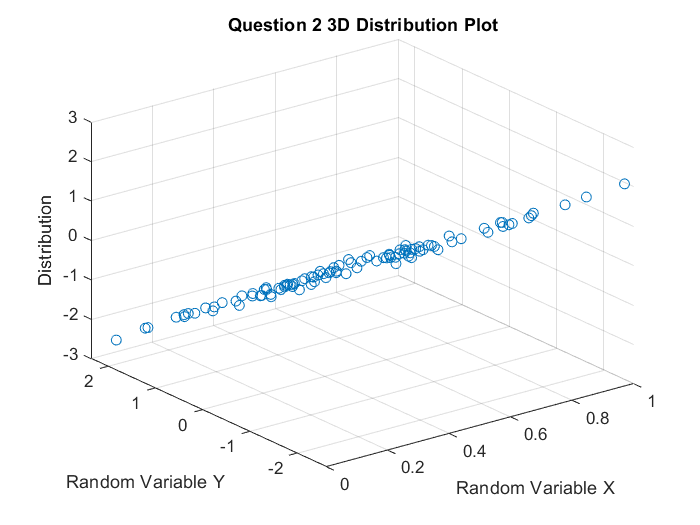


title('Question 2 3D Distribution Plot')
xlabel('Random Variable X') 
ylabel('Random Variable Y')
zlabel('Distribution') 

Question 2's 2D contourr plot from the estimated p(x)


Q22D = contour(Q2Distribution)

Q22D =    -2.5000    2.0000    1.9948    2.0000   -2.5000    2.0000    1.9955    2.0000   -2.5000    2.0000    1.9602    2.0000   -2.5000    1.0000    1.0287    1.0000   -2.0000    2.0000    1.8883    2.0000   -2.0000    2.0000    1.9178    2.0000   -2.0000    2.0000    1.8888    2.0000   -2.0000    2.0000    1.9839    1.8613    2.0000   -2.0000    1.0000    1.1334    1.0000   -2.0000    1.0000    1.0877    1.0000   -2.0000    2.0000    1.9207    2.0000   -1.5000    2.0000    1.7818    1.8808    2.0000
    3.0000    2.9900    3.0000    3.0402    3.0000   28.9923   29.0000   29.0073    3.0000   55.6860   56.0000   56.0557    3.0000   59.0531   59.0000   58.9551    3.0000    2.7875    3.0000    3.8556    3.0000   16.8859   17.0000   17.4075    3.0000   28.8109   29.0000   29.1788    4.0000   54.9576   55.0000   56.0000   56.1940    3.0000   59.2468   59.0000   58.7915    3.0000   66.1162   66.0000   65.5317    3.0000   97.8334   98.0000   98.1442    4.0000    2.5850    3.0000    4.0000  

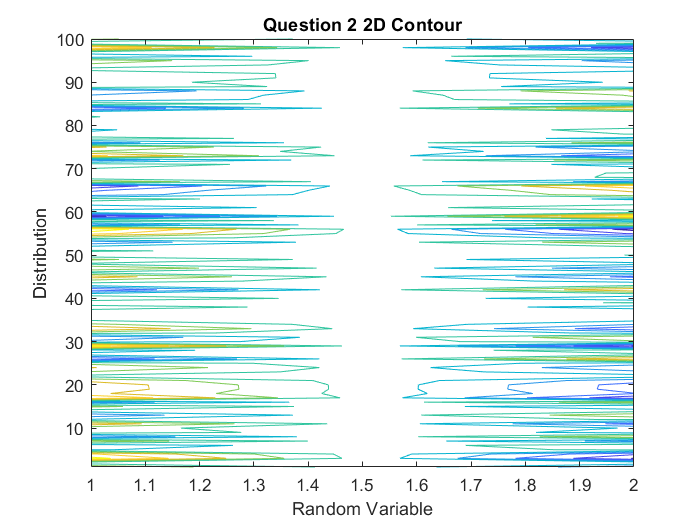

title('Question 2 2D Contour')
xlabel('Random Variable') 
ylabel('Distribution') 

Question 3's 3D plot from the estimated p(x)

parzenSum = 0

parzenSum = 0

count = 0

count = 0

Q3Distribution = zeros(100,1);
for j = 1:100;
currentWindow = RandomVariables(j,1);
exponential = -((initialMean-currentWindow)*(initialMean-currentWindow)')/2*.01^2;
currentParzen = 1/(((2*(pi))^2.5))*exp(exponential);
count = count + 1;
random = RandomVariables(j);
Q3Distribution(j,1) = currentParzen;

end

Q23D = scatter3(RandomVariables,Q2DistributionCol1,Q2DistributionCol1)

Q23D =   Scatter with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1×100 double]
              YData: [1×100 double]
              ZData: [1×100 double]
              CData: [0 0.4470 0.7410]

  Show all properties


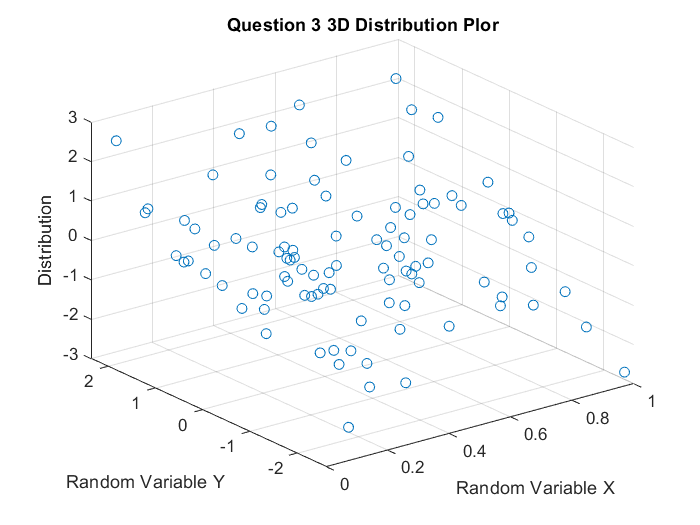

title('Question 3 3D Distribution Plor')
xlabel('Random Variable X') 
ylabel('Random Variable Y')
zlabel('Distribution') 

Question 3's 2D contourr plot from the estimated p(x)

contourDimensions(1,:) = RandomVariables

contourDimensions =     0.3311    0.0717    0.9647    0.2714    0.5285    0.0847    0.3765    0.2771    0.2888    0.3022    0.0103    0.5916    0.7729    0.3809    0.2012    0.4538    0.4284    0.5337    0.4271    0.0261    0.1105    0.2513    0.0262    0.1003    0.3141    0.9603    0.5366    0.6026    0.6497    0.4801    0.8632    0.6402    0.9970    0.7971    0.9890    0.2680    0.1318    0.7195    0.3061    0.5737    0.1643    0.2522    0.3327    0.4760    0.6600    0.4155    0.3414    0.2530    0.0045    0.3500
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.010

contourDimensions(2,:) = Q3Distribution

contourDimensions =     0.3311    0.0717    0.9647    0.2714    0.5285    0.0847    0.3765    0.2771    0.2888    0.3022    0.0103    0.5916    0.7729    0.3809    0.2012    0.4538    0.4284    0.5337    0.4271    0.0261    0.1105    0.2513    0.0262    0.1003    0.3141    0.9603    0.5366    0.6026    0.6497    0.4801    0.8632    0.6402    0.9970    0.7971    0.9890    0.2680    0.1318    0.7195    0.3061    0.5737    0.1643    0.2522    0.3327    0.4760    0.6600    0.4155    0.3414    0.2530    0.0045    0.3500
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.010

Q32D = contour(contourDimensions)

Q32D =     0.1000    1.8908    1.0000    0.1000    5.9656    5.0000    4.0000    3.0000    2.0317    0.1000   10.6927   10.0000    9.0000    8.0000    7.0000    6.0524    0.1000   19.8157   19.0000   18.0000   17.0000   16.0000   15.0000   14.0000   13.0000   12.0000   11.1543    0.1000   22.6721   22.0000   21.0000   20.8752    0.1000   48.6157   48.0000   47.0000   46.0000   45.0000   44.0000   43.0000   42.0000   41.0000   40.0000   39.0000   38.0000   37.0000   36.0000   35.0000   34.0000   33.0000
    2.0000    1.0000    1.7200    5.0000    1.0000    1.8266    1.6560    1.9058    1.0000    6.0000    1.0000    1.6922    1.6775    1.6633    1.7546    1.0000   10.0000    1.0000    1.7844    1.8283    1.7851    1.7974    1.5295    1.7575    1.8822    1.8454    1.0000    4.0000    1.0000    1.6274    1.1049    1.0000   27.0000    1.0000    1.6299    1.7287    1.7782    1.8617    1.8070    1.7213    1.6287    1.4169    1.8405    1.6963    1.8733    1.2611    1.6514    1.9082    1.8858  

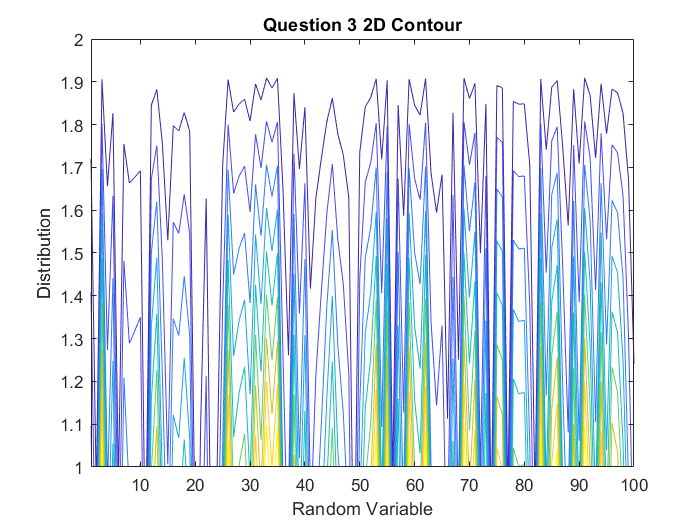

title('Question 3 2D Contour')
xlabel('Random Variable') 
ylabel('Distribution') 